# SVM Regression with Hyperparameters optimization

## Generate some dataset with non linearly separable classes

Classes can be non linearly separable in $R^2$, but they can be separable if "mapped" into higher dimensional space.

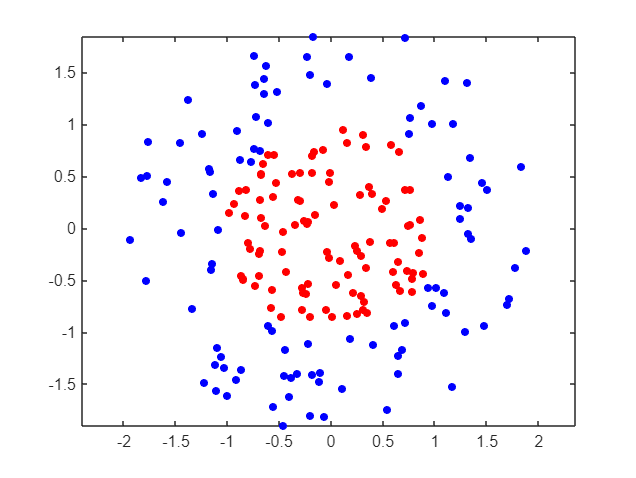

r = sqrt(rand(100 ,1));                 % random radius
t = 2*pi*rand(100 ,1);                  % random angle
data1 = [r.* cos(t), r.* sin(t)];       % points of class -1 (RED )

r2 = sqrt(3*rand(100 ,1) +1);           % random radius for ring
t2 = 2* pi*rand (100,1);                % random angle for ring
data2 = [r2 .* cos(t2), r2 .* sin(t2)]; % points of class +1 ( BLUE )
data3  = [data1; data2];                % merge data together

figure
plot(data1(:,1), data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1), data2(:,2),'b.','MarkerSize',15)
axis equal
hold off

## Run Support Vector Regression with automatic Hyperparameters optimization

y = franke(data3(:,1), data3(:,2));

opt = struct('AcquisitionFunctionName' ,'expected-improvement-plus')

opt = struct with fields:
    AcquisitionFunctionName: 'expected-improvement-plus'


|====================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |      Epsilon |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.39017 |    0.094655 |     0.39017 |     0.39017 |    0.0033716 |       202.47 |     0.022404 |
|    2 | Best   |     0.35853 |    0.068249 |     0.35853 |     0.36029 |        120.4 |       1.5296 |       29.177 |
|    3 | Accept |     0.35853 |    0.060497 |     0.35853 |     0.35852 |     0.057214 |    0.0094147 |       30.931 |
|    4 | Accept |     0.38302 |     0.05666 |     0.35853 |     0.35852 |       46.147 |        790.7 |   0.00057205 |
|    5 | Accept |     0.35853 |    0.050147 |   

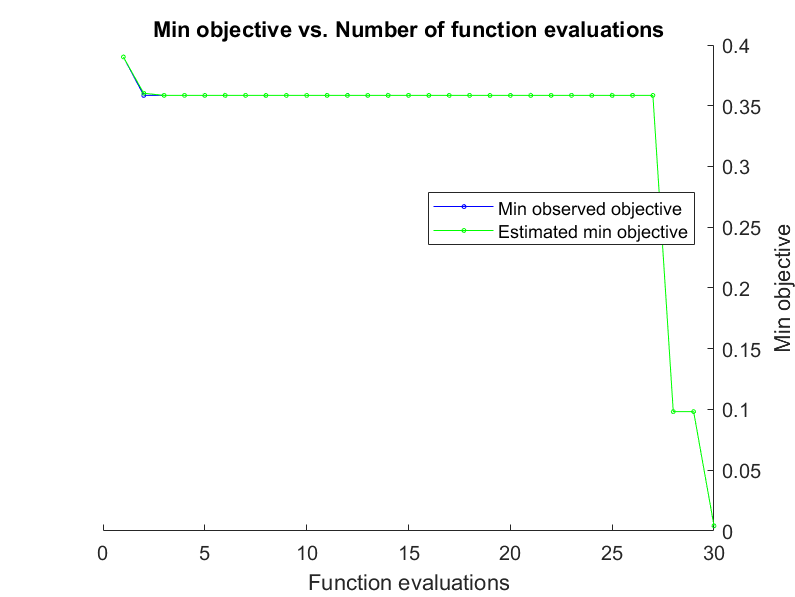


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 26.1671 seconds
Total objective function evaluation time: 12.6332

Best observed feasible point:
    BoxConstraint    KernelScale     Epsilon 
    _____________    ___________    _________

       614.38          1.4772       0.0039787

Observed objective function value = 0.0042927
Estimated objective function value = 0.0043171
Function evaluation time = 10.9686

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale     Epsilon 
    _____________    ___________    _________

       614.38          1.4772       0.0039787

Estimated objective function value = 0.0043171
Estimated functi

regSVM_Optim =   RegressionSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                    ResponseTransform: 'none'
                                Alpha: [124×1 double]
                                 Bias: 0.2559
                     KernelParameters: [1×1 struct]
                      NumObservations: 200
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                       BoxConstraints: [200×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [200×1 logical]
                               Solver: 'SMO'


  Properties, Methods



regSVM_Optim = fitrsvm (data3 ,y, 'KernelFunction', 'rbf',...
      'OptimizeHyperparameters','auto' ,...
      'HyperparameterOptimizationOptions',opt)



bestHyper = bestPoint(regSVM_Optim.HyperparameterOptimizationResults)  % table

bestHyper = 1×3 table
    BoxConstraint    KernelScale     Epsilon 
    _____________    ___________    _________

       614.38          1.4772       0.0039787



bestHyper.Epsilon

ans = 0.0040

bestHyper.BoxConstraint

ans = 614.3829

bestHyper.KernelScale

ans = 1.4772